close all;
clear;
clc;


## Question 2

## Part 1

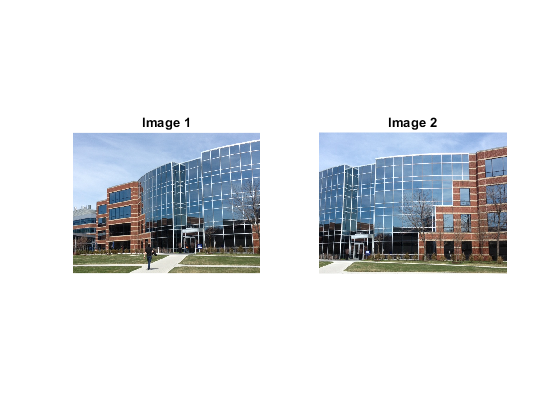

building1 = im2double(imread("building\building1.JPG"));
building2 = im2double(imread("building\building2.JPG"));

figure();
subplot(1,2,1);
imshow(building1, []);
title("Image 1");

subplot(1,2,2);
imshow(building2, []);
title("Image 2");

## Part 2

addpath('sift');

building1_gray = rgb2gray(building1);
building2_gray = rgb2gray(building2);

[frames1,descr1] = sift(building1_gray);
[frames2,descr2] = sift(building2_gray);


## Part 3

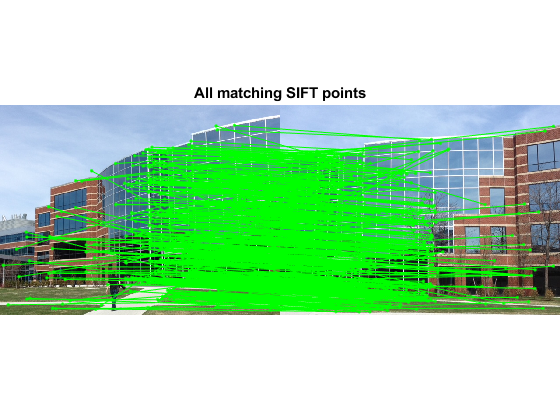


matches = siftmatch(descr1, descr2);
figure();
plotmatches(building1, building2, frames1, frames2, matches);
title('All matching SIFT points');